# Sample Problem 21-02b

clear
constant

k =      8.99e+09

e0 =      8.85e-12

syms L q qp k epsilon_0 real positive
syms x real

q1 = 8*q, q2 = -2*q

$$q1 = 8\,q$$

$$q2 = -2\,q$$

Force acting on the proton due to $q_1$ where x is position of the proton

Fp1 = 1/(4*pi*epsilon_0)*q1*qp/x^2*sign(x)

$$Fp1 = \frac{2\,q\,\mathrm{qp}\,\mathrm{sign}\left(x\right)}{\epsilon_{0}\,x^{2}\,\pi }$$

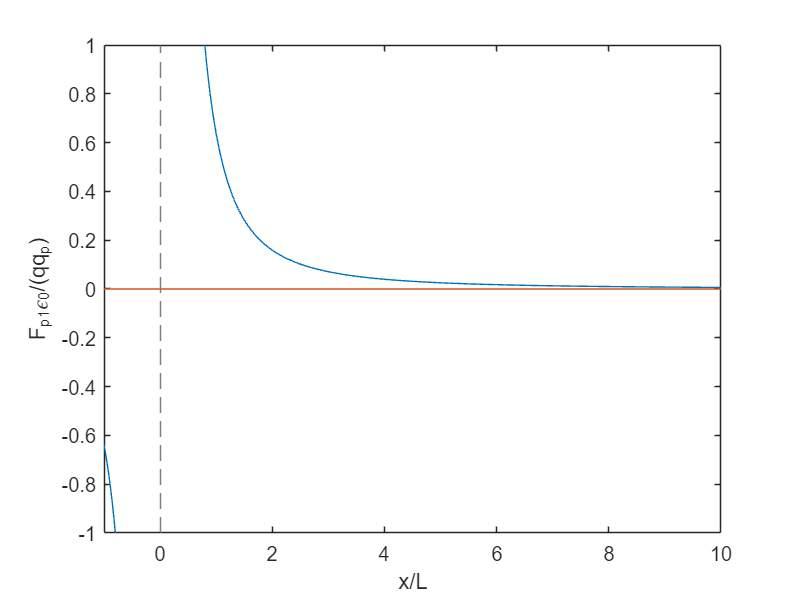

    fplot([subs(Fp1,[q,qp,epsilon_0],[1,1,1]) 0])
    ylim([-1 1]), xlim([-1 10])
    xlabel('x/L'), ylabel('F_{p1}\epsilon_0/(qq_p)')

Force acting on the proton due to $q_2$

Fp2 = 1/(4*pi*epsilon_0)*q2*qp/(x-L)^2*sign(x-L)

$$Fp2 = \frac{q\,\mathrm{qp}\,\mathrm{sign}\left(L-x\right)}{2\,\epsilon_{0}\,\pi \,{\left(L-x\right)}^{2}}$$

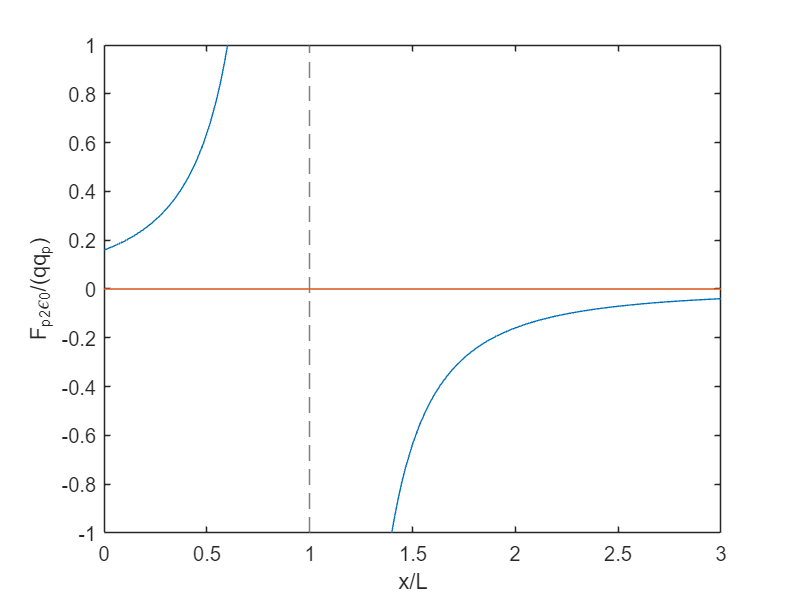

    fplot([subs(Fp2,[q,qp,epsilon_0,L],[1,1,1,1]) 0])
    ylim([-1 1]), xlim([0 3])
    xlabel('x/L'), ylabel('F_{p2}\epsilon_0/(qq_p)')

Net force acting on the proton

Fpnet = Fp1+Fp2

$$Fpnet = \frac{2\,q\,\mathrm{qp}\,\mathrm{sign}\left(x\right)}{\epsilon_{0}\,x^{2}\,\pi }+\frac{q\,\mathrm{qp}\,\mathrm{sign}\left(L-x\right)}{2\,\epsilon_{0}\,\pi \,{\left(L-x\right)}^{2}}$$

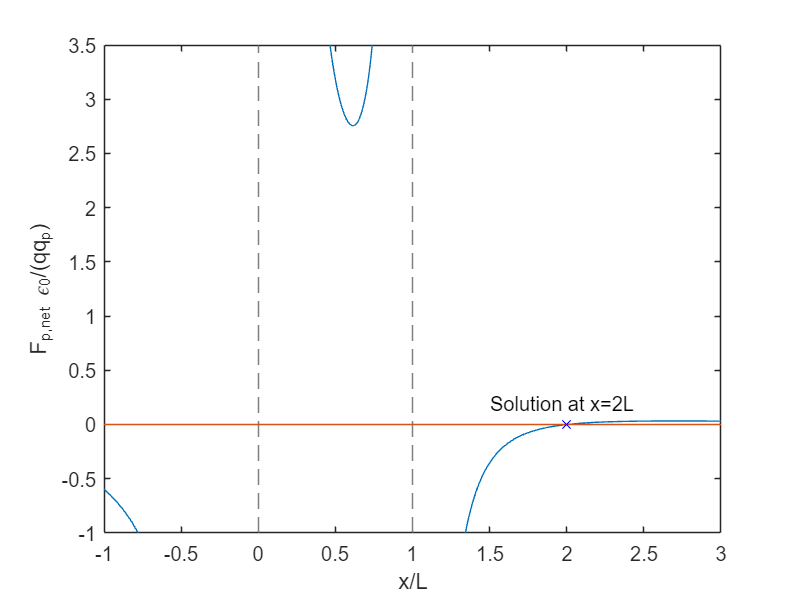

fplot(subs([Fpnet 0],[q,qp,epsilon_0,L],[1,1,1,1]))
    ylim([-1 3.5]), xlim([-1 3])
    xlabel('x/L'), ylabel('F_{p,net} \epsilon_0/(qq_p)')
    hold on, plot(2,0,'bx'), text(1.5,0.2,'Solution at x=2L')

Solve the equilibrium equation for x

xsol = solve(Fpnet==0,x)

$$xsol = 2\,L$$

#### ANSWER: around x = 2L, it is unstable.